**PUNTO 8**

Importar datos y calcular vector de media

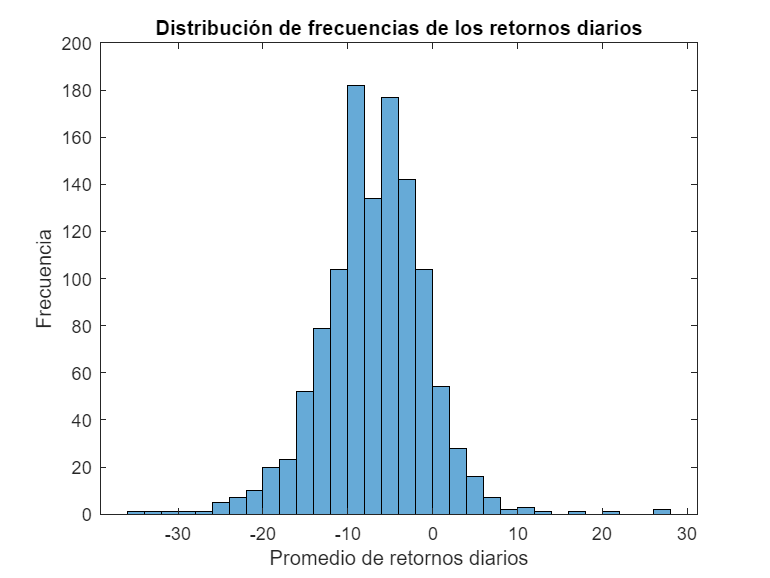

% Importar datos
clearvars
clc
load data38.mat

% Calcular vector de medias
Vm = mean(data38,2);

% Histograma de los retornos diarios
histogram(Vm); 
title('Distribución de frecuencias de los retornos diarios')
xlabel('Promedio de retornos diarios')
ylabel('Frecuencia')

**Definir variable binaria**

umbral = mean([min(Vm) max(Vm)])

umbral = -3.8653

Vb = zeros(numel(Vm),1);
Vb(Vm > umbral) = 1;

**Definir matriz binaria**

MB = zeros(size(data38,1), size(data38,2));
MB(data38 > 0) = 1

MB =      1     1     0     1     0     1     1     1     1     0     0     0     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     1     0     0     0     0     1     0     1     0     0
     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     1     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     0     1     0     1     0     0     0
     0     0     0     1     0     1     1     1     0     0     1     0     0     1     0     0     0     1     1     0     1     0     1     0     0     1     1     0     1     0     0     0     0     1     0     1     0     0
     0     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     1     0     0     0     1     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     0     1     1     0 

%s = jaccard(MB(:,1), Vb);

**Cálculo de métricas binarias**

% Ciclo para calcular métricas de cada activo
m = size(MB,2);
Index = zeros(m,3);
for i = 1:m
    A = MB(:,i);
    B = Vb;
    [Index(i,1), Index(i,2), Index(i,3)] = Santy(A,B);
end

% Creando columnas para tabla
Activo = (1:m)';
Pearson = Index(:,1);
Jaccard = Index(:,2);
Dice = Index(:,3);
index_medio = mean([Pearson Jaccard Dice],2);

% Top 10 con base en el promedio de los tres Índices
Portfolio = table(Activo, Pearson, Jaccard, Dice, index_medio);
Sorted = sortrows(Portfolio,"Index_medio")

Sorted = 38×5 table
    Activo    Pearson    Jaccard       Dice      Index_medio
    ______    _______    ________    ________    ___________

      32      0.10502    0.020173    0.039548     0.054914  
      31      0.23867     0.14905     0.25943      0.21572  
      29      0.22862     0.34492     0.51292      0.36215  
      27      0.23952     0.34974     0.51823      0.36916  
       7      0.24164     0.35065     0.51923      0.37051  
       3      0.26253     0.35918     0.52853      0.38341  
      17      0.27881     0.36712     0.53707      0.39434  
       2      0.28306     0.36893     0.53901        0.397  
      15      0.28563     0.37077     0.54097      0.39912  
       1      0.30527      0.3798     0.55052      0.41186  
       6      0.31219     0.38312     0.55399      0.41643  
       4      0.

% 10 activos menos pareceidos al vector binario de medias
Different10 = Sorted(1:10,1)

Different10 = 10×1 table
    Activo
    ______

      32  
      31  
      29  
      27  
       7  
       3  
      17  
       2  
      15  
       1  


% 10 activos más pareceidos al vector binario de medias
Similar10 = Sorted(end-9:end,1)

Similar10 = 10×1 table
    Activo
    ______

      22  
      23  
      26  
      16  
      10  
      33  
      36  
      20  
      11  
      30  


**Función de métricas binarias**

function [pearson, jaccard, dice] = Santy(A,B)
    a = sum(A + B == 2);
    b = sum(A==0 & B==1);
    c = sum(A==1 & B==0);
    d = sum(A + B == 0);
    pearson = (a*d-b*c) / sqrt((a+c)*(b+d)*(a+b)*(c+d));
    jaccard = a / (a+b+c);
    dice = 2*a / (2*a+b+c);
end